# Review #2

## step zero

clear
close all

## Param

xstep=50;
xstart=50;
xend=1400;

vstep=25;
vstart=25;
vend=500;

k=1; % coef risk
b=0.25*10^-4;


## Decesion variables

x=xstart:xstep:xend;
disp(["length(x)= ",length(x)])

    "length(x)= "    "28"



v=vstart:vstep:vend;
disp(["length(v)= ",length(v)])

    "length(v)= "    "20"



## Objective funcitons

% x is horizontal, column number = length(x)
% v is vertical, row number = length(y)
Pollution=x.*v'.^2;  % 20*28
Profit=(15-2*x./v').*x-b.*x.*v'.^2;  % 20*28
Risk=k*x;  % 1*28
Risk_scale=(Risk-min(Risk))/(max(Risk)-min(Risk));
Profit_scale=(Profit-min(min(Profit)))./(max(max(Profit))-min(min(Profit))); % 20*28
Pollution_scale=(Pollution-min(min(Pollution)))./(max(max(Pollution))-min(min(Pollution))); % 20*28

## Q1

only the profits

disp(["Maximum profit is ",max(max(Profit))])

    "Maximum profit is "    "6234.375"



% find the x and v corresponded
[ilig icol]=find(Profit==max(max(Profit)));
% ilig for v, icol for x
disp(["x corresponded is ", x(icol)])

    "x corresponded is "    "1050"



disp(["v corresponded is ", v(ilig)])

    "v corresponded is "    "350"



## Q2

max profit, with a given fishing zone. Find best speed

### Decision space

askip ça sert à rien ici....

% figure(1)
% hold on
% % x pour l'axe des abcisses
% % v pour l'axe des ordonnées
% for i=1:length(x)
%     for j=1:length(v)
%        plot(x(i),v(j),'ko') ;
%     end
% end


### Profit "space"

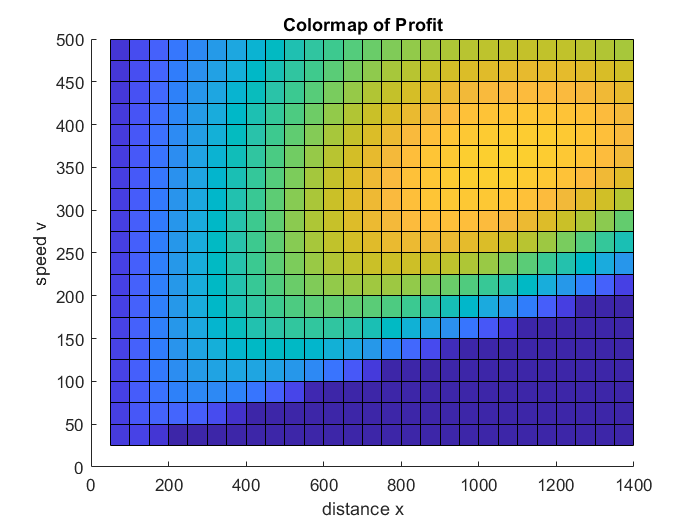

figure(2)
hold on
pcolor(x,v,Profit)
caxis([0,7000])
title("Colormap of Profit")
xlabel("distance x")
ylabel("speed v")

% given fishing zone ...
% = pour chaque x, trouver un v
% 应该有一条贯穿左右的线
% 即找到每一列的最大值，返回一个向量，和矩阵的列数相同
% = length(x)

max(Profit) % the max Profit for each given x

ans = 	1.0e+03 *

    0.6905    1.3104    1.8780    2.4000    2.8780    3.3203    3.7231    4.0950    4.4269    4.7365    5.0102    5.2500    5.4708    5.6583    5.8125    5.9490    6.0593    6.1388    6.1876    6.2232    6.2344    6.2170    6.1710    6.1013    6.0221    5.9164    5.7839    5.6248


[ilig icol]=find(Profit==max(Profit))

ilig =      5
     6
     7
     8
     9
     9
    10
    10
    10
    11


icol =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


% c'est ilig qui nous intéresse
v_q2=v(ilig)

v_q2 =    125   150   175   200   225   225   250   250   250   275   275   300   300   300   300   325   325   325   325   350   350   350   350   375   375   375   375   375


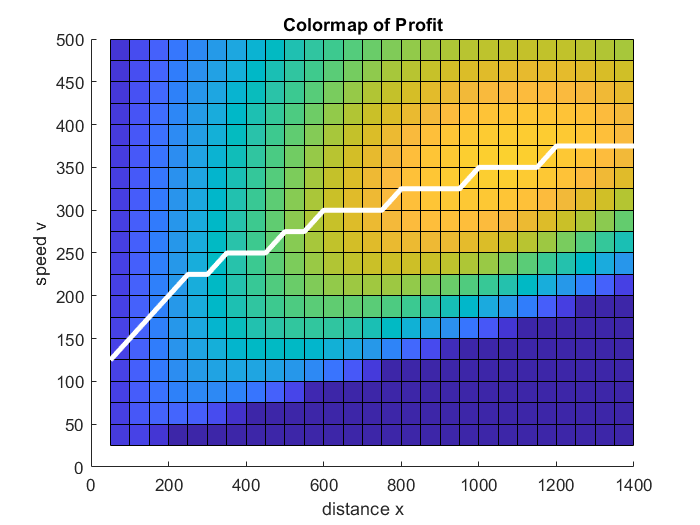

figure(2)
plot(x,v_q2,'w-','LineWidth',3)

## Q3

#### method 1

we have already the max profit for each given x

with each given x, we have a risk

so this is a game between two vectors

% the vector for x for max profit :
ProfitQ3=max(Profit);
% scale it :
ProfitQ3_scale=(ProfitQ3-min(ProfitQ3))/(max(ProfitQ3)-min(ProfitQ3)); % one min is sufficient, this is vector but not matrix
Risk_scale; % already computed
lambda=0.5; % lambda is with profit
ws_Q3=lambda*ProfitQ3_scale+(1-lambda)*(1-Risk_scale) % bigger the better

ws_Q3 =     0.5000    0.5374    0.5701    0.5986    0.6232    0.6446    0.6624    0.6774    0.6888    0.6982    0.7044    0.7075    0.7089    0.7073    0.7027    0.6965    0.6879    0.6766    0.6624    0.6471    0.6296    0.6095    0.5869    0.5621    0.5364    0.5084    0.4779    0.4450



% the maximum score is :
disp(["The max ws is ",max(ws_Q3)])

    "The max ws is "    "0.70891"




% find where it is :
ilig=find(ws_Q3==max(ws_Q3));
disp(["Its index is ",ilig])

    "Its index is "    "13"



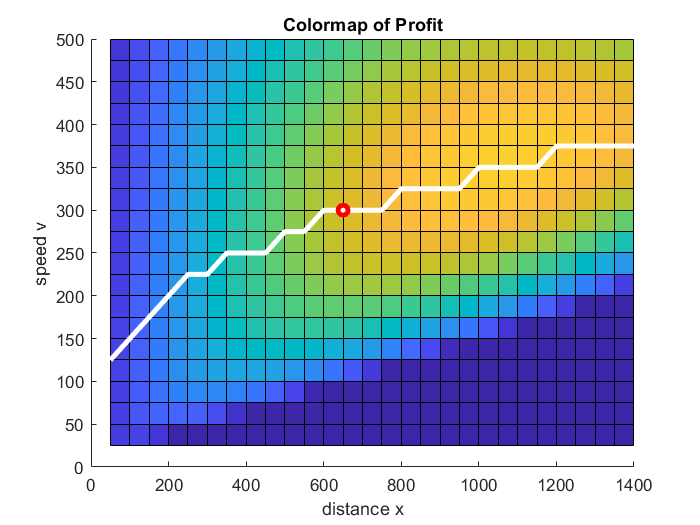


% plot it
figure(2)
plot(x(ilig),v_q2(ilig),'ro','LineWidth',3)

## Q4

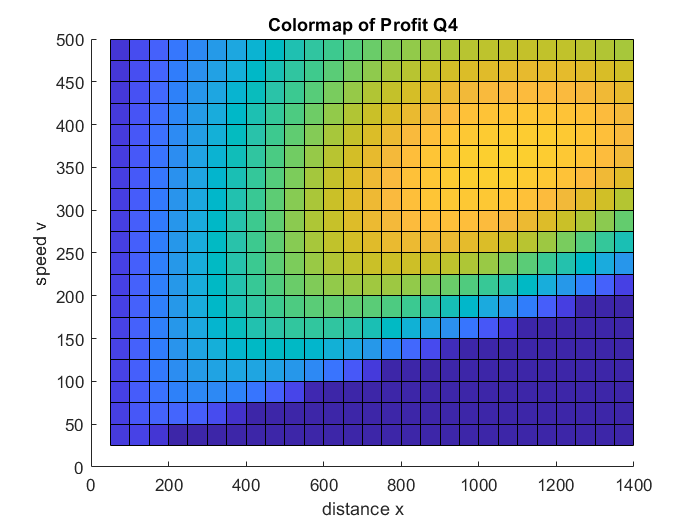

figure(3)
hold on
pcolor(x,v,Profit)
caxis([0,7000])
title("Colormap of Profit Q4")
xlabel("distance x")
ylabel("speed v")

max(Profit,[],2);
[a,b]=find(Profit==max(Profit,[],2))

a =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


b =      2
     4
     6
     7
     9
    11
    12
    14
    15
    17


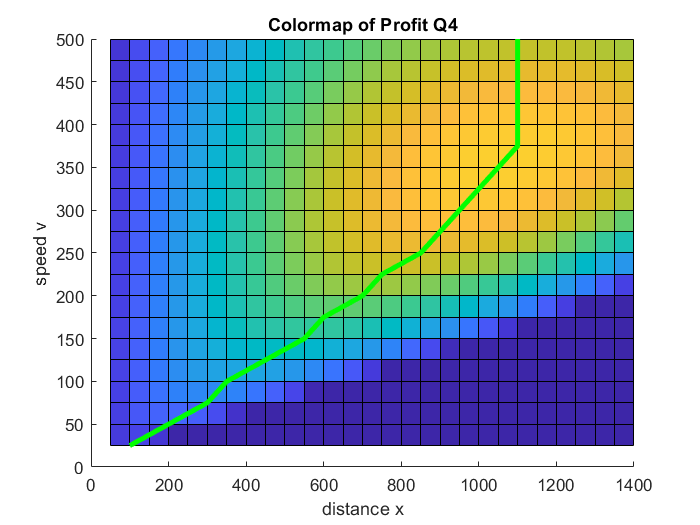

% what we want is b
figure(3)
plot(x(b),v,'g-','LineWidth',3)

## Q5

Pareto for profit-consumption.

We want to max profit and min consumption.

feat. Pollution_scale & Profit_scale

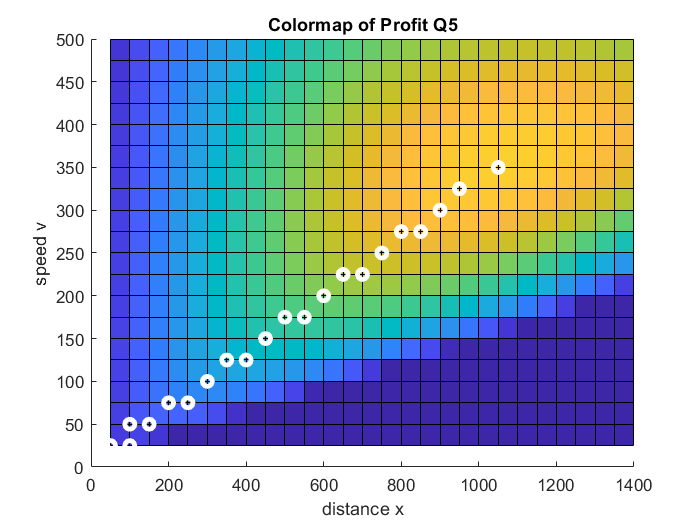

figure(4)
hold on
pcolor(x,v,Profit)
caxis([0,7000])
title("Colormap of Profit Q5")
xlabel("distance x")
ylabel("speed v")

for lambda=0:0.01:1 % lambda is with Profit
WSQ5=Profit_scale*lambda+(1-lambda)*(1-Pollution_scale); % 20*28
% disp(["The max score is" max(max(WSQ5))])
[ilig icol]=find(WSQ5==max(max(WSQ5)));
% ilig for v, icol for x
plot(x(icol),v(ilig),'wo','LineWidth',3)
end

## Q7

three criteria

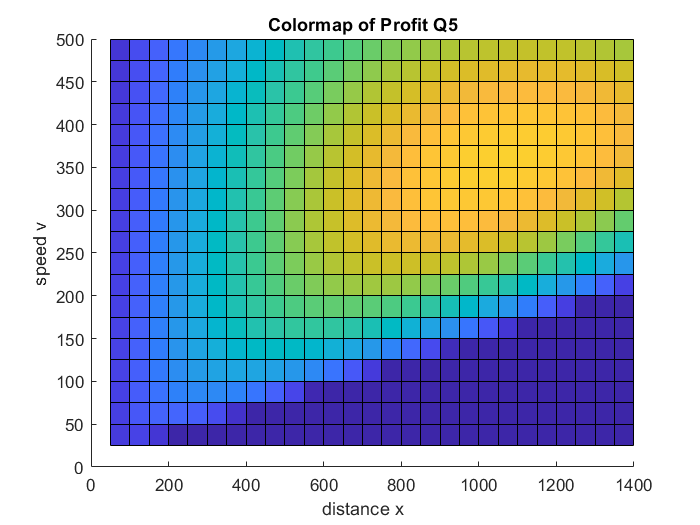

figure(5)
hold on
pcolor(x,v,Profit)
caxis([0,7000])
title("Colormap of Profit Q5")
xlabel("distance x")
ylabel("speed v")


% lam1=0.3; % lam1 is with Profit
% lam2=0.3; % lam2 is with Pollution
step=0.05

step = 0.0100

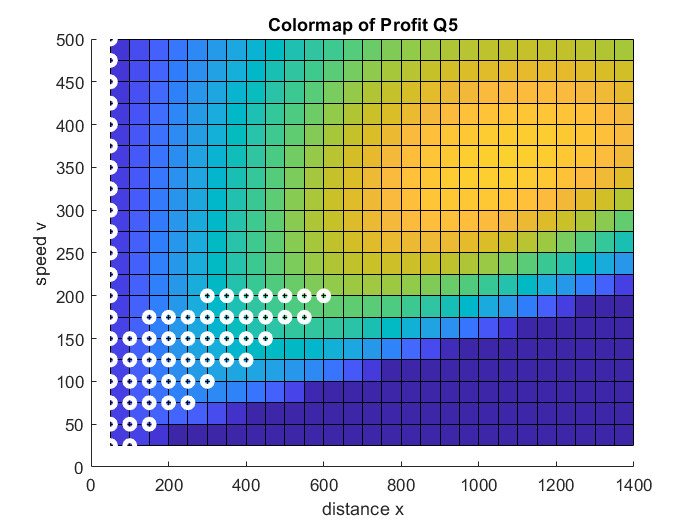

Risk_scale7=Risk_scale.*ones(length(v),1);
for lam1=0:step:0.9
    for lam2=0:step:1-lam1
        
            % make a WS which we will maximise
            ws7=lam1*Profit_scale+lam2*(1-Pollution_scale)+(1-lam1-lam2)*(1-Risk_scale7);
            [ilig icol]=find(ws7==max(max(ws7)));
            plot(x(icol),v(ilig),'wo','LineWidth',3)
        
    end
end

## test

a=[1 2 3 ; 4 5 6; 7 8 9;10 11 12 ]

a =      1     2     3
     4     5     6
     7     8     9
    10    11    12


max(a,[],1)

ans =     10    11    12


max(a)

ans =     10    11    12
